%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% demo_graphical_learning_spectral_clustering.m
%
% 75-minute graphical learning recitation, Example 2:
% Spectral clustering / community detection from the graph Laplacian.
%
% Message to students:
%   From Griffin Ch. 5, we already know:
%   - the graph Laplacian L = D - A,
%   - the multiplicity of eigenvalue 0 counts connected components,
%   - the Fiedler vector (eigenvector of lambda_2) gives a natural bipartition.
%
% Real-world interpretation:
%   We want to discover groups in a social network / citation graph / customer
%   similarity graph without knowing labels in advance.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;


%% ------------------------------------------------------------------------
% STEP 1. Build a graph with two clear communities and a weak bridge
% -------------------------------------------------------------------------
% We build two dense clusters weakly linked by a few cross edges.

n1 = 8; n2 = 8;
A1 = ones(n1) - eye(n1);      % clique on first 8 nodes
A2 = ones(n2) - eye(n2);      % clique on second 8 nodes
A = blkdiag(A1,A2);

% Add a few weak links between the two blocks
cross_edges = [4,10; 5,11; 7,13];
for k = 1:size(cross_edges,1)
    i = cross_edges(k,1);
    j = cross_edges(k,2);
    A(i,j) = 1; A(j,i) = 1;
end

G = graph(A);
n = numnodes(G);


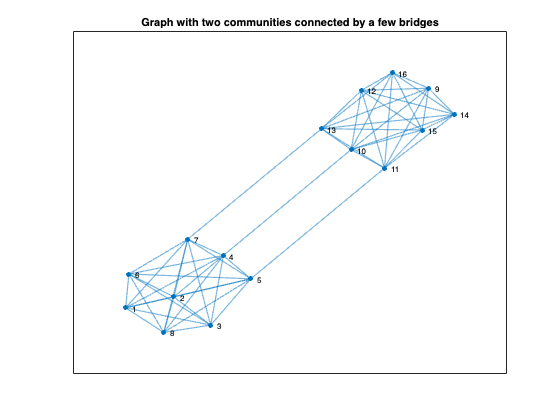

%% ------------------------------------------------------------------------
% STEP 2. Visualize the graph
% -------------------------------------------------------------------------
figure('Color','w','Name','Spectral clustering: original graph');
p = plot(G,'Layout','force','LineWidth',1.2);
title('Graph with two communities connected by a few bridges');

%% ------------------------------------------------------------------------
% STEP 3. Build Laplacian and compute its spectrum
% -------------------------------------------------------------------------
d = degree(G);
D = diag(d);
L = D - A;

% Eigen-decomposition (graph is small, so eig is fine)
[V,Lambda] = eig(L);
eigvals = diag(Lambda);
[eigvals,idx] = sort(eigvals,'ascend');
V = V(:,idx);

lambda1 = eigvals(1);
lambda2 = eigvals(2);
fiedler = V(:,2);

fprintf('Smallest eigenvalues of L:\n');

Smallest eigenvalues of L:


for k = 1:min(5,numel(eigvals))
    fprintf('  lambda_%d = %.6f\n', k, eigvals(k));
end

  lambda_1 = -0.000000
  lambda_2 = 0.641101
  lambda_3 = 8.000000
  lambda_4 = 8.000000
  lambda_5 = 8.000000


fprintf('Fiedler value lambda_2 = %.6f\n', lambda2);

Fiedler value lambda_2 = 0.641101


%% ------------------------------------------------------------------------
% STEP 4. Spectral partition by sign of the Fiedler vector
% -------------------------------------------------------------------------
cluster1 = find(fiedler >= 0);
cluster2 = find(fiedler < 0);

fprintf('\nCluster 1 nodes: '); fprintf('%d ', cluster1); fprintf('\n');


Cluster 1 nodes: 9 10 11 12 13 14 15 16 


fprintf('Cluster 2 nodes: '); fprintf('%d ', cluster2); fprintf('\n');

Cluster 2 nodes: 1 2 3 4 5 6 7 8 


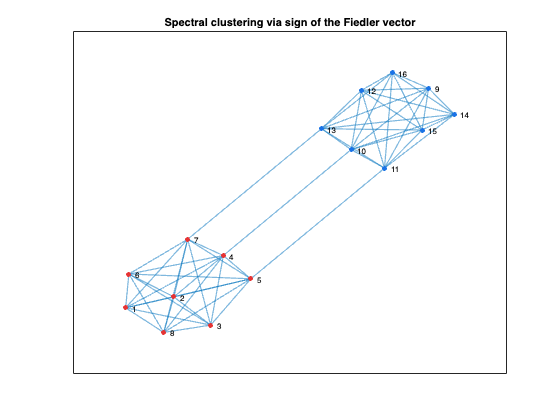

%% ------------------------------------------------------------------------
% STEP 5. Visualize the clustering on the graph
% -------------------------------------------------------------------------
figure('Color','w','Name','Spectral clustering result');
p2 = plot(G,'Layout','force','LineWidth',1.2);
title('Spectral clustering via sign of the Fiedler vector');

% reset all nodes to gray first
highlight(p2, 1:n, 'NodeColor', [0.7 0.7 0.7]);
% then color the two groups
highlight(p2, cluster1, 'NodeColor', [0.1 0.45 0.9]);
highlight(p2, cluster2, 'NodeColor', [0.9 0.2 0.2]);

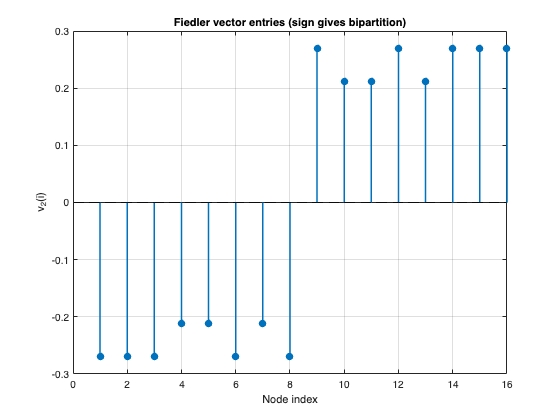

%% ------------------------------------------------------------------------
% STEP 6. Plot the Fiedler vector entries directly
% -------------------------------------------------------------------------
figure('Color','w','Name','Fiedler vector entries');
stem(1:n, fiedler, 'filled','LineWidth',1.5);
xlabel('Node index'); ylabel('v_2(i)');
title('Fiedler vector entries (sign gives bipartition)');
grid on;
yline(0,'k--');

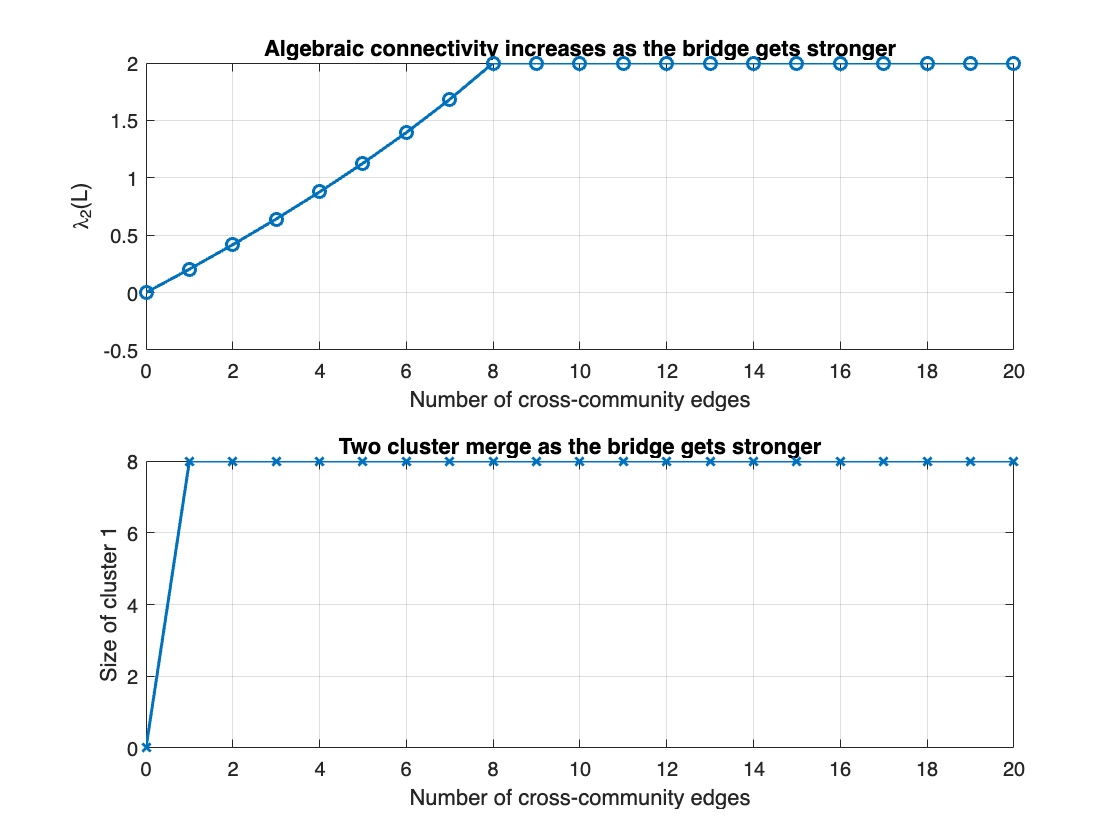

%% ------------------------------------------------------------------------
% STEP 7. Show how lambda_2 changes as bridge strength changes
% -------------------------------------------------------------------------
% This connects the spectral quantity to "how well connected" the graph is.
bridgeCounts = 0:20;
lambda2_list = zeros(size(bridgeCounts));
cluster1_list = zeros(size(bridgeCounts));

for m = 1:numel(bridgeCounts)
    Atemp = blkdiag(A1,A2);
    c = bridgeCounts(m);
    for j = 1:c
        i1 = mod(j-1,n1)+1;
        i2 = n1 + mod(j-1,n2)+1;
        Atemp(i1,i2) = 1;
        Atemp(i2,i1) = 1;
    end
    Ltemp = diag(sum(Atemp,2)) - Atemp;
    [V,Lambda] = eig(Ltemp);
    eigvals = diag(Lambda);
    [eigvals,idx] = sort(eigvals,'ascend');
    V = V(:,idx);

    lambda1 = eigvals(1);
    lambda2 = eigvals(2);
    fiedler = V(:,2);

    lam = sort(eig(Ltemp),'ascend');
    lambda2_list(m) = lam(2);
    cluster1_list(m) = length(find(fiedler < 0));
end

figure('Color','w','Name','Fiedler value vs bridge count');
subplot 211
plot(bridgeCounts, lambda2_list, 'o-','LineWidth',1.5);
xlabel('Number of cross-community edges');
ylabel('\lambda_2(L)');
title('Algebraic connectivity increases as the bridge gets stronger');
grid on;

subplot 212
plot(bridgeCounts, cluster1_list, 'x-','LineWidth',1.5);
xlabel('Number of cross-community edges');
ylabel('Size of cluster 1');
title('Two cluster merge as the bridge gets stronger');
grid on;

%% ------------------------------------------------------------------------
% TEACHING NOTES
% -------------------------------------------------------------------------
% 1. The Laplacian already appeared in Griffin Ch. 5.
% 2. The Fiedler vector is not an abstract theorem: it is a practical group-
%    finding device.
% 3. This is unsupervised learning on graphs: no labels, only structure.
% 4. Everything comes from linear algebra on L = D - A.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
